# Figures Script

This script produces figures seen in *Temporal Dynamics of Viral Load and False Negative Rate Influence the Levels of Testing Necessary to Combat COVID19 Spread *by Jarvis and Kelley. The script loads all the r0s from running the model. 

## R0 data from all the scenarios

load('r0_all')

####    Scenarios

 Scenario 1: “Perfect tests, Uniform Spread” where we assume no period of undetectability, no false negative rate, and a uniform chance of transmission equal to 2.5 / 14. 

r0(1)={scenario1_perfect_r0};

   Scenario 2: “Simple Undetectability, Fast Spread” where we assume that the virus is not detectable until 2 days prior to symptom onset, and then has a 5% false negative rate after that point. This condition uses the He et al. viral load data to scale the R0, which results in ~45% of transmissivity prior to symptom onset. 

r0(2)={scenario2_simple_r0};

     Scenario 3: “Dynamic False Negative, Slow Spread.” This uses the day-by-day false negative rates reported by Kucirka et al for testing (Figure 1). For transmissivity, we use the day-by-day positive rates from the Kucirka et al data as a stand-in for viral load (Figure 4F). The shape of this profile still biases spread early in the disease, but not as early as the He et al. viral load data. 

r0(3)={scenario3_slowspread_r0};

    Scenario 4: “Dynamic False Negative, Fast Spread.” This scenario uses the day-by-day false negative rates from Kucirka et al. for testing, and the He et al. viral load data to scale transmissivity.

r0(4)={scenario4_dynamicfast_r0};

Scenario 4 with 70% compliance with masking

r0(5)={scenario4_masking70_r0};

###  Conditions

Each Scenario is run with 5%, 25%, 50%, 75% and 100% of the student tested (test_conditions) at testing frequencys from daily to once a week and once every other week (freq_conditions). The test_conditions are the rows and freq_conditions are the columns of each.  

tests_conditions=[500,2500:2500:10000];
freq_conditions=[1:7,14];

Map is used to create a color map for the heatmap which r0 below 1 are shades of blue and above one are yellow/red.

map=[0, 0, 0.05; 0, 0, 0.2; 0, 0, 0.35; 0, 0, 0.5;0, 0, 0.65; 0, 0, 0.8;0, 0, 0.95;0, 0, 1.0;...
    1.0000,1,0;1.0000,0.92,0;1.0000,0.84,0;1.0000,0.76,0;1.0000,0.68,0;1.0000,0.60,0;1.0000,0.52,0;1.0000,0.44,0;...
    1.0000,0.36,0;1.0000,0.28,0;1.0000,0.20,0;1.0000,0.12,0];

### Obtaining the Median and 95th Percentile

The for loop finds the median and 95th percentile for each scenario and in each variation of condition.

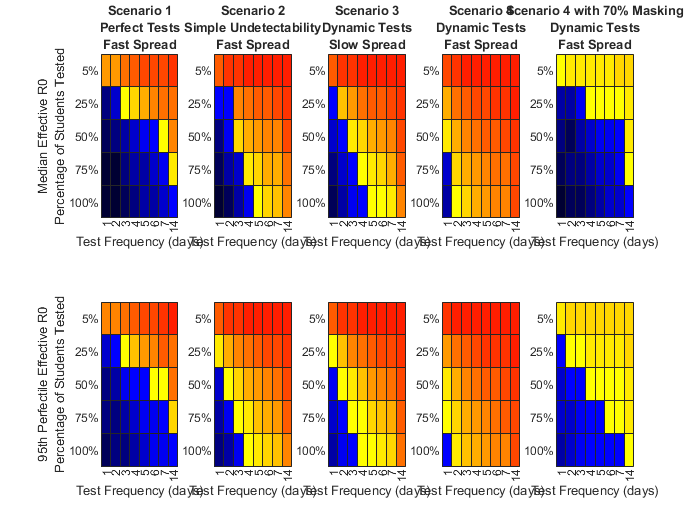

figure();
for i=1:size(r0,2) %for each scenario
    for j=1:size(r0{1,i},1) %for each percent of students tested
        for k=1:size(r0{1,i},2) %for each frequency of test
            
            %Find the Median
            r0_median{1,i}(j,k) = cellfun(@median,r0{1,i}(j,k));
            
            %Sort the 100 r0 sample
            r0_sorted=cellfun(@sort,r0{1,i}(j,k),'UniformOutput',false);
            
            %The 95th one is the 95th percentile
            r0_95upper{1,i}(j,k)=r0_sorted{1,1}(95,1);
        end
    end    
    
    %% Making a heatmap
    %The heatmap's first row is the effective r0 medians for each scenario and 
    % the second row is each scenario's 95th percentile.
    
    subplot(2,size(r0,2),i) %make a subplot (each scenario in one graph)
    
    %Make a heatmap of each scenario's median r0 
    heatmap(r0_median{1,i},'colorlimits',[0,2.5], 'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7,'ColorbarVisible','off')
    
    xlabel('Test Frequency (days)') %x axis label
    
    %Titles for each scenario (specified in the beginning of the script)
    if i==1
        title({'Scenario 1','Perfect Tests','Fast Spread'})
        xlabel('Test Frequency (days)')
        ylabel({'Median Effective R0','Percentage of Students Tested'}) %y axis label
    elseif i==2
        title({'Scenario 2','Simple Undetectability','Fast Spread'})
    elseif i==3
        title({'Scenario 3','Dynamic Tests','Slow Spread'})    
    elseif i==4
        title({'Scenario 4','Dynamic Tests','Fast Spread'})
    else
        title({'Scenario 4 with 70% Masking','Dynamic Tests','Fast Spread'}) 
    end
    
    subplot(2,size(r0,2),i+size(r0,2)) %make a subplot (each scenario in one graph)
    %Make a heatmap of each scenario's 95th percentile r0 
    heatmap(r0_95upper{1,i},'colorlimits',[0,2.5], 'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7,'ColorbarVisible','off')
    
    xlabel('Test Frequency (days)') %x axis label
    if i==1
       ylabel({'95th Perfectile Effective R0','Percentage of Students Tested'}) %y axis label

    end
end

## Plot False Negative Rates

### Load Data

This section produces the figure which shows the apparent false negative rate based on detectability. Each scenario is based on a one day semester which 100% of the students (10,000 students) are sick. Each student is at a various stage of infection progression. 

%This loads mat files of 3 scenarios.
load("apparentfalsenegativerates.mat")

To test how viral load detectability effects the false negative rate, 3 scenarios were developed calculate the apparent false negative rate. The following puts all the files into a cell array in order to calculate the median, and 95% confidence interval efficiently.

- Testresults_undetectbefore loads data of 10,000 sick students who are undetectable until 2 days before their symptoms start (based on the He et al viral load)

- Testresults_dynamicfalseneg loads data of 10,000 sick students who are detectable based on the kucirka et al false negative rates

- Testresults_perfect  loads data of 10,000 sick students who are detectable at all times

falseneg_tests(1)={Testresults_undetectbefore};
falseneg_tests(2)={Testresults_dynamicfalseneg};
falseneg_tests(3)={Testresults_perfect};

### Calculate the False Negative Rates 

The below for loops calculate the median and 95% confidence interval for each scenario to calculate the apparent false negative rate.

for i=1:size(falseneg_tests,2) %for each scenario
     for j=1:size(falseneg_tests{1,i},1) %for each sample (100 samples)
         
        % Find who was sick (all students)
        totalsick=size(falseneg_tests{1, i}{j, 1},1); 
        
        % Who tested positive
        testedpositive(i,j)=sum(falseneg_tests{1, i}{j, 1}(:,1)); 
        
        %Calculate percent who was false negative
        falsenegativepercent_pertest(i,j)=1-testedpositive(i,j)/totalsick; 
     end
     
     %Find the Median for each scenario
     falsenegativepercent_median(i)=median(falsenegativepercent_pertest(i,:));
     
     %Sort the False Negative Percent in order to calculate 95% Confidence
     %Interval
     falsenegativepercent_sorted=sort(falsenegativepercent_pertest(i,:));
     falsenegativepercent_error(i,1)=falsenegativepercent_sorted(97);
     falsenegativepercent_error(i,2)=falsenegativepercent_sorted(3);      
 end
 

### Plot Bar Graph of Apparent False Negative Rate

Each scenario is plotted as a bar in the bar graph to show how each scenario's viral load greatly effects the apparent false negative rate of testing.

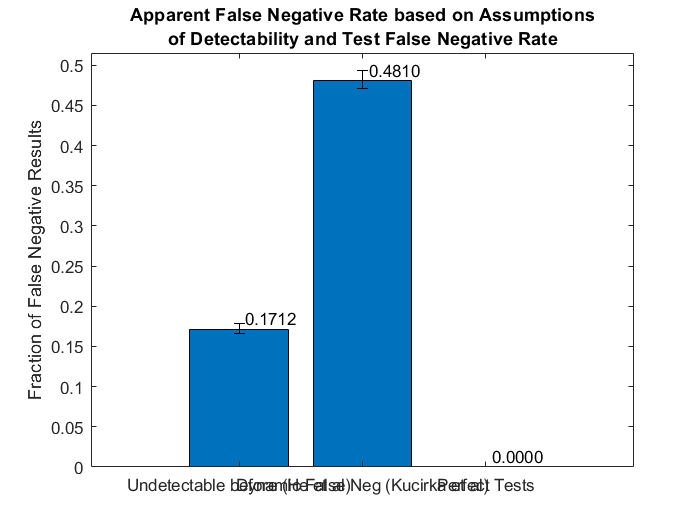

 figure();
 
 %Plot the median of each scenario
bar(falsenegativepercent_median)
hold on

%based on 95% Confidence Interval
er=errorbar(1:size(falseneg_tests,2), falsenegativepercent_median,...
    transpose(falsenegativepercent_median)-falsenegativepercent_error(:,1),...
    falsenegativepercent_error(:,2)- transpose(falsenegativepercent_median));

%Style of the error bars
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
title({'Apparent False Negative Rate based on Assumptions','of Detectability and Test False Negative Rate'}) %Title
somenames={'Undetectable before (He et al)'; 'Dynamic False Neg (Kucirka et al)';'Perfect Tests' }; %X axis labels
set(gca,'xticklabel',somenames) %X axis labels
hold on
ylabel('Fraction of False Negative Results') %y axis label
ylim([0,max(falsenegativepercent_error(:,2))+max(falsenegativepercent_error(:,2))*0.1]) %increase y axis limits

%Adding test of the False Negative fraction for clarity
for i=1:size(falseneg_tests,2)
    text(i+0.05, falsenegativepercent_median(i),num2str( falsenegativepercent_median(i),'%0.4f'),...
        'HorizontalAlignment','left',...
        'VerticalAlignment','bottom')
end